load("DynamicsData.mat")

test4 = struct with fields:
        time: [13440×1 double]
    throttle: [13440×1 double]
      thrust: [13440×1 double]
     current: [13440×1 double]


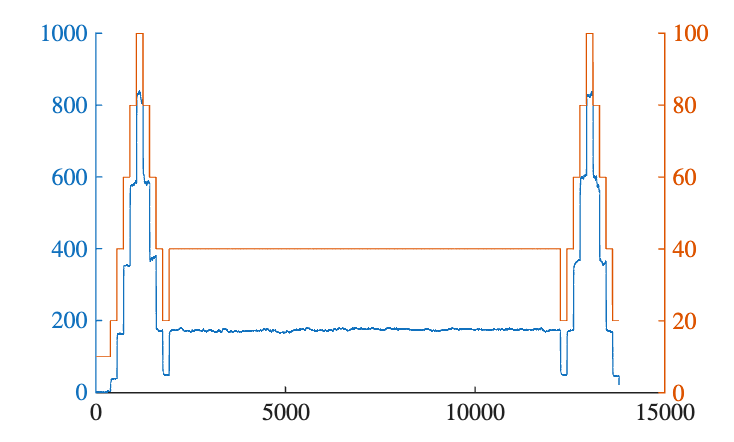

figure, clf, hold on
yyaxis left
plot(test1.thrust)
yyaxis right
plot(test1.throttle)
hold off

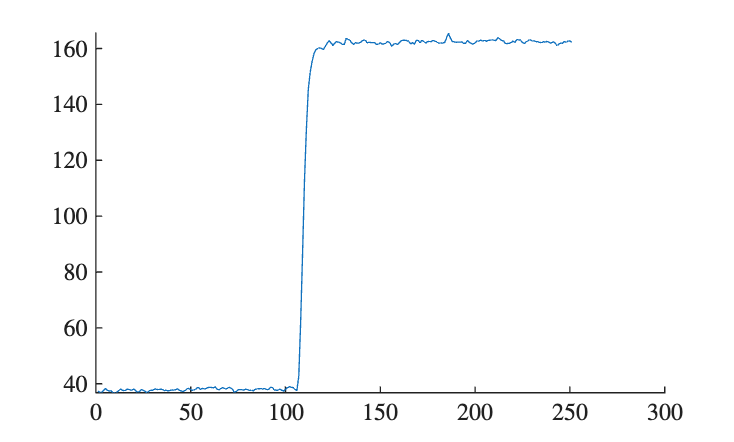


figure, clf, hold on
plot(test1.thrust(450:700))
hold off

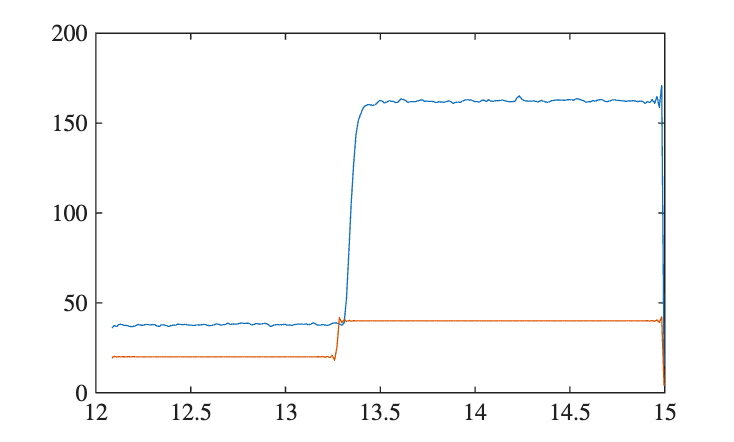


[thrustResampled, timeResampled] = resample(test1.thrust(450:700), test1.time(450:700),80);
[throttleResampled, ~] = resample(test1.throttle(450:700), test1.time(450:700),80);

plot(timeResampled, thrustResampled, timeResampled, throttleResampled)


data = iddata(thrustResampled,throttleResampled,1/80);

sys = tfest(data,2,0)


sys =
 
  From input "u1" to output "y1":
           -6.922
  -------------------------
  s^2 + 2.809 s + 6.029e-10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: -41.54%                  
FPE: 7862, MSE: 7533                             
 
Model Properties


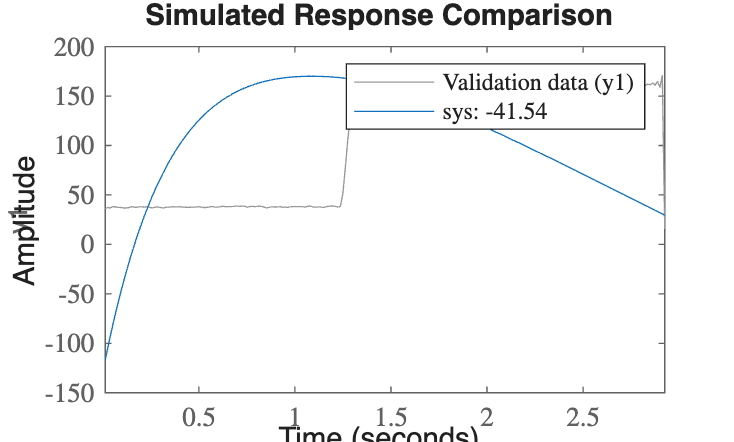


compare(sys,data)